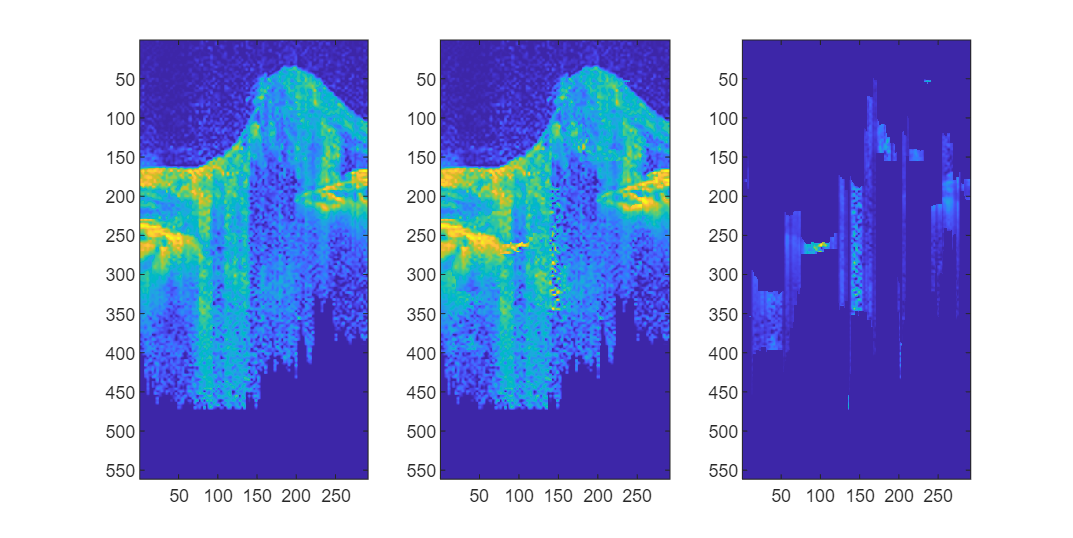

dbstop if error
current_path = pwd;
cd D:/OCT/newdata/patient_001/left1(micron)_png/yz;
name = num2str(321);
Xori = double(im2gray(imread(strcat(name,'.png'))));
figure();
set(gcf, 'Position',  [0, 0, 800, 400])
hold on;
f1 = subplot(1,3,1); % fig 1 \|/
clim = [1,255];
imagesc(Xori,clim);
X=Xori;
[nrow,ncol] = size(X);
bestlist = zeros(3,ncol);
for epoch = 1:1
    for idxcol = 2:ncol
        mini = Inf; % min norm of Xi-1-Xi
        mb=1;nb=nrow;kb=0;
        best = [mb,nb,kb];
        Y = X(:,idxcol-1) - X(:,idxcol);
        for m = 3:nrow-3
            if mean(X(m+1:m+3,idxcol)) > (sum(X(m-2:m,idxcol))-min(X(m-2:m,idxcol)))/2
                YX = Y.*X(:,idxcol);
                YXrs = [0; YX];
                for tmp = 2:nrow
                    YXrs(tmp,1) = YXrs(tmp,1) + YXrs(tmp-1,1);
                end
                XX = X(:,idxcol).^2;
                XXrs = [0; XX];
                for tmp = 2:nrow
                    XXrs(tmp,1) = XXrs(tmp,1) + XXrs(tmp-1,1);
                end
                YYnorm = norm(Y);
                for n = m+1:nrow
                    Xmn = zeros(nrow,1);
                    Xmn(m:n,1) = X(m:n,idxcol);
                    k = max(0,Y'*Xmn/(Xmn'*Xmn));
%                     k = max(0,(YXrs(m+1,1)-YXrs(n,1))/(XXrs(m+1,1)-XXrs(n,1)));
                    if k > 0
    %                     Xmn = zeros(nrow,1);
    %                     Xmn(m:n,1) = X(m:n,idxcol);
                        L = norm(Y-k*Xmn)^2;
%                         L = k^2*(XXrs(m+1,1)-XXrs(n,1))-2*k*(YXrs(m+1,1)-YXrs(n,1))+YYnorm^2;
                        if L < mini
                            mini = min(mini, L);
                            best = [m,n,k];
                        end
                    end
                end
            end
        end
        mb=best(1);nb=best(2);kb=best(3);
        X(mb:nb,idxcol) = (kb+1)*X(mb:nb,idxcol); 
        bestlist(:,idxcol)=best';
    end
end

f2 = subplot(1,3,2); % fig 1 \|/
imagesc(X,clim);
f3 = subplot(1,3,3);
imagesc(abs(X-double(Xori))*10);

cd(pwd);


$$\begin{array}{l}
\mathrm{For}\;i=2:\mathrm{end}\_\mathrm{of}\_X\_\mathrm{col}\\
\mathrm{minimize}\;L_i =||\left(X_{i-1}^{\left(1\right)} -X_i^{\left(1\right)} \right)||_2 \\
s\ldotp t\ldotp X_i^{\left(1\right)} =X_i^{\left(0\right)} +{k_i X}_{i,\left(m_i \;,n_i \right)}^{\left(0\right)} \\
\;\;\;\;\;\;\;\;\;k_i \ge 0\\
\;\;\;\;\;\;\;{\bar{X} }_{i,\left(m_i +3,m_i +1\right)} >\frac{{\left(\max +\mathrm{secondmax}\right)X}_{i,\left(m_{i-2} ,m_i \right)} }{2}
\end{array}$$



$$\begin{array}{l}
\mathrm{For}\;i=2:\mathrm{end}\_\mathrm{of}\_X\_\mathrm{col}\\
\mathrm{minimize}\;L_i =||\left(X_{i-1}^{\left(1\right)} -X_i^{\left(1\right)} \right)||_2^2 \\
=||\left(X_{i-1}^{\left(1\right)} -X_i^{\left(0\right)} \right)-k_i X_{i,\left(m_i ,n_i \right)}^{\left(0\right)} ||_2^2 =||Y_i -k_i X_{i,\left(m_i ,n_i \right)}^{\left(0\right)} ||_2^2 \\
\left.={\left(X_{i,\left(m_i ,n_i \right)}^{\left(0\right)} \right.}^{\prime } X_{i,\left(m_i ,n_i \right)}^{\left(0\right)} \right)k^2 -2{Y_i }^{\prime } X_{i,\left(m_i ,n_i \right)}^{\left(0\right)} \;k+{Y_i }^{\prime } Y_i \\
\left.a={\left(X_{i,\left(m_i ,n_i \right)}^{\left(0\right)} \right.}^{\prime } X_{i,\left(m_i ,n_i \right)}^{\left(0\right)} \right)>0\left(\mathrm{otherwise}\;\mathrm{trivial}\right)\\
\mathrm{对称轴}:\frac{{Y_i }^{\prime } X_{i,\left(m_i ,n_i \right)}^{\left(0\right)} }{\left.{\left(X_{i,\left(m_i ,n_i \right)}^{\left(0\right)} \right.}^{\prime } X_{i,\left(m_i ,n_i \right)}^{\left(0\right)} \right)}\\
\Rightarrow k_{i,\;\mathrm{opt}} \left(m_i ,n_i \right)=\max \left\lbrace \frac{{Y_i }^{\prime } X_{i,\left(m_i ,n_i \right)}^{\left(0\right)} }{\left.{\left(X_{i,\left(m_i ,n_i \right)}^{\left(0\right)} \right.}^{\prime } X_{i,\left(m_i ,n_i \right)}^{\left(0\right)} \right)},0\right\rbrace \\
=\max \left\lbrace \frac{{Y_i }^{\prime } I_{\left(m_i ,n_i \right)} X_i^{\left(0\right)} }{{X_i^{\left(0\right)} }^{\prime } I_{\left(m_i ,n_i \right)} X_i^{\left(0\right)} },0\right\rbrace \\
s\ldotp t\ldotp X_i^{\left(1\right)} =X_i^{\left(0\right)} +{k_i X}_{i,\left(m_i \;,n_i \right)}^{\left(0\right)} \\
\;\;\;\;\;\;\;\;Y_i \overset{\triangle }{=} \left(X_{i-1}^{\left(1\right)} -X_i^{\left(0\right)} \right)=\left(X_{i-1}^{\left(0\right)} -X_i^{\left(0\right)} \right)+k_{i-1} X_{i-1,\left(m_{i-1} ,n_{i-1} \right)}^{\left(0\right)} \\
\;\;\;\;\;\;\;\;\;k_i \ge 0\\
\;\;\;\;\;\;\;{\bar{X} }_{i,\left(m_i +3,m_i +1\right)} >\frac{{\left(\max +\mathrm{secondmax}\right)X}_{i,\left(m_{i-2} ,m_i \right)} }{2}
\end{array}$$
